# Control Design for a Floating Wind Turbine (Part 1)

## Robust Control [SC42145]

### Delft Center for Systems and Control

### Delft University of Technology

Authors:

Friso Vijverberg (6437745)

Freya van Apeldoorn (5524539)

Douwe Brogtrop (4877810)

clc;
load('.\Assignment_Data_SC42145_2025.mat'); % Load data

### SISO Control Design

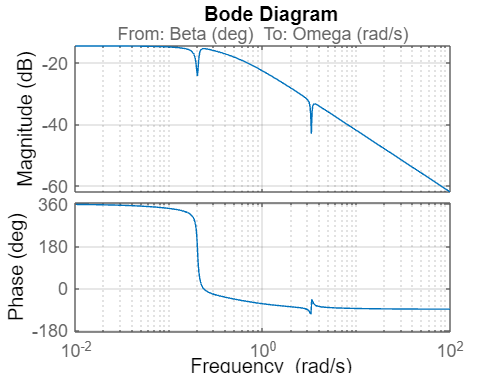

% SISO plant: Blade pitch beta to generator speed \omega_r
G_siso = -FWT(1, 1);

% Quetsion 1:

% 1. Open loop bode plot (with margins)
bode(G_siso);
grid on

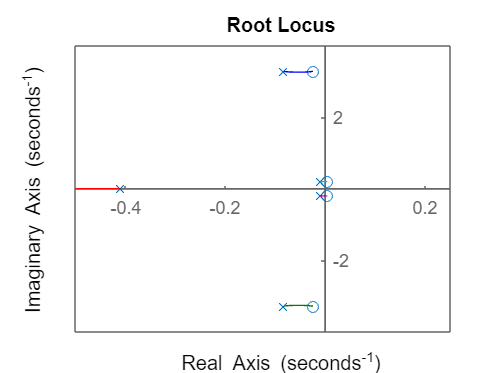


% 2. Root locus 
figure;
rlocus(G_siso);                  % Create root locus plot

xlim([-0.5 0.25]);                % Set x-limits
ax = gca;                        % Get current axes
ax.XAxisLocation = 'origin';     % X-axis through origin
ax.YAxisLocation = 'origin';     % Y-axis through origin
ax.Box = 'on';                  % Remove box
grid off;                        % No grid

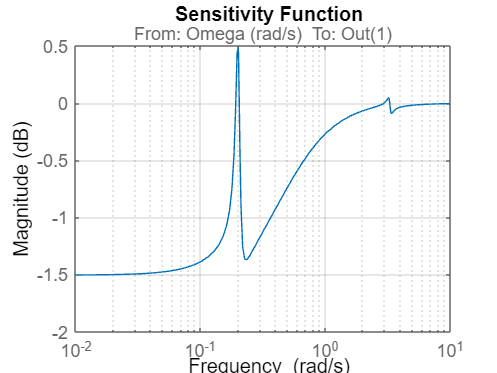


% 3. Sensitivity plot
S = 1/(1+G_siso);
bodemag(S);
title('Sensitivity Function');
grid on;

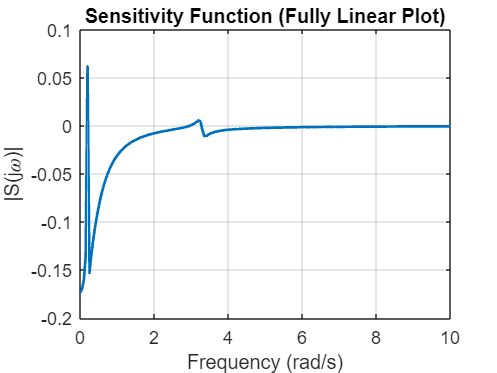


w = linspace(0, 100, 2000);  % choose suitable max freq
[mag, ~] = bode(S, w);
mag = squeeze(mag);

figure;
plot(w, log(mag), 'LineWidth', 1.5);
grid on;
xlabel('Frequency (rad/s)');
xlim([0, 10])
ylabel('|S(j\omega)|');
title('Sensitivity Function (Fully Linear Plot)');

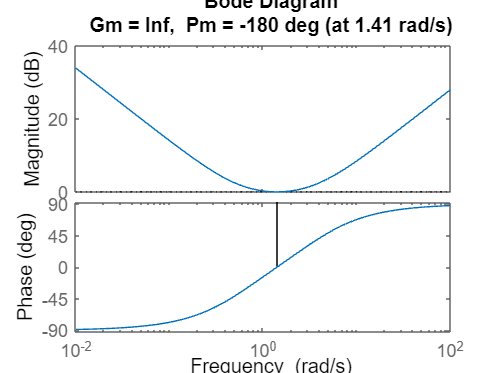

% GM > 0 ideally > 6, Pm between 30, 60

% Initial guess 1, 1, 0 (need to move up the plot and have decent margins)
% increasing by a factor of 10 reduces gain margin 
% x0.1 also provides inferior perfomance
% Adjusted so that Kp > Ki > Kd
% 1, 0.5, 0.25 
% 9, 0.5, 0 bad step response

Kp = 1; % Move the plot up to get a reasonable phase margin
Ki = 0.5; % Required for gain margin
Kd = 0.25; % Reduces oscillation

controller = pid(Kp, Ki, Kd);

L_siso = series(controller, G_siso); % Loop transfer function

% Bode plot (including margins) for the controller and loop transfer
% fucnction
margin(controller)

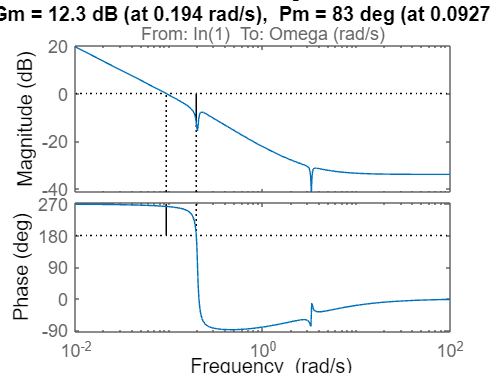

margin(L_siso)

2 states removed.


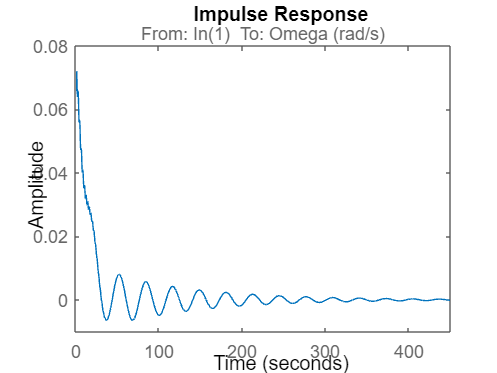


% Closed loop system
CL_siso = feedback(L_siso, 1);

% Plot time-domain responses
impulse(minreal(CL_siso))

2 states removed.


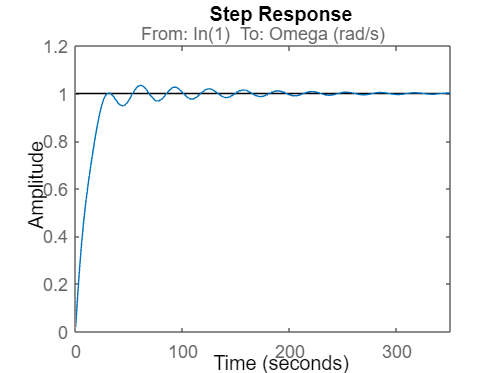

step(minreal(CL_siso))

[P_sim, t, y] = stepWind_out(FWT, controller);

% Perfomance metrics for step-like responses
S = stepinfo(CL_siso);

disp(['Rise Time: ', num2str(S.RiseTime), ' s']);

Rise Time: 20.5893 s


disp(['Settling Time: ', num2str(S.SettlingTime), ' s']);

Settling Time: 111.3681 s


disp(['Overshoot: ', num2str(S.Overshoot), ' %']);

Overshoot: 3.4251 %


disp(['Steady-State Value: ', num2str(S.SettlingMin), ' to ', num2str(S.SettlingMax)]);

Steady-State Value: 0.90321 to 1.0343


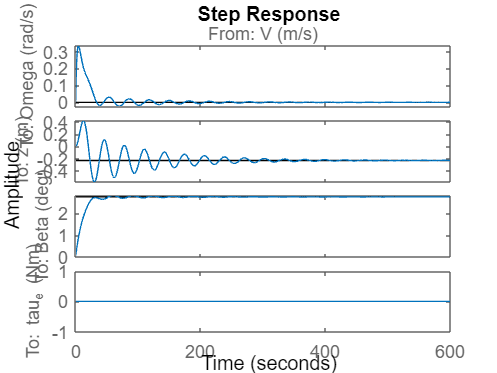


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 2.4622     | 200.4243   | NaN        | 9503.1496  | 0.3325     | 4.1858     | 0.0002    
z (m)                     | 2.0459     | 513.1359   | 153.6302   | 182.4512   | 0.5809     | 30.2852    | -0.2290   
Beta (deg)                | 20.4071    | 78.1105    | 2.3257     | -0.0000    | 2.8232     | 60.0780    | 2.7590    
tau_e (Nm)                


performance_list = {CL_siso, P_sim(1,1), P_sim(2,1), P_sim(3,1), P_sim(4,1)};

stepWind(FWT, controller)


% Performance metrics for impulse-like responses
for i = 1:4
    yi = y(:,i);       
    y0 = yi(end);      
    e = yi - y0;       

    peak_dev = max(abs(e));

    eps = 0.02 * peak_dev;  % Recovery time based on 2% of peak value 
    idx = find(abs(e) > eps, 1, 'last');
    if isempty(idx)
        recovery_time = 0;
    else
        recovery_time = t(idx);
    end

    bw = bandwidth(P_sim(i, 1));

    disp(['Output ', num2str(i)]);
    disp(['Peak deviation: ', num2str(peak_dev)]);
    disp(['Recovery time: ', num2str(recovery_time), ' s']);
    disp(['Bandwidth: ', num2str(bw), ' rad/s']);
    disp('------------------------------------');
end

Output 1


Peak deviation: 0.33254


Recovery time: 200.4243 s


Bandwidth: Inf rad/s


------------------------------------


Output 2


Peak deviation: 0.64693


Recovery time: 385.3366 s


Bandwidth: 0.37034 rad/s


------------------------------------


Output 3


Peak deviation: 2.705


Recovery time: 78.2984 s


Bandwidth: 0.10632 rad/s


------------------------------------


Output 4


Peak deviation: 0


Recovery time: 0 s


Bandwidth: Inf rad/s


------------------------------------


### Mixed Sensitivity Design

% Compute RGA

G_mix = -ss([tf(FWT(1,1)) tf(FWT(1,2)); ...
        tf(FWT(2,1)) tf(FWT(2,2))]);

w = 0;   % frequency in rad/s
Gw_0 = freqresp(G_mix, w); 
RGA_0 = Gw_0.*inv(Gw_0).'

RGA_0 =    -0.6554    1.6554
    1.6554   -0.6554



w = 0.3*2*pi; % frequency in rad/s
Gw_03 = freqresp(G_mix, w);
RGA_03 = Gw_03.*inv(Gw_03).'

RGA_03 =   -0.0283 + 0.1398i   1.0283 - 0.1398i
   1.0283 - 0.1398i  -0.0283 + 0.1398i


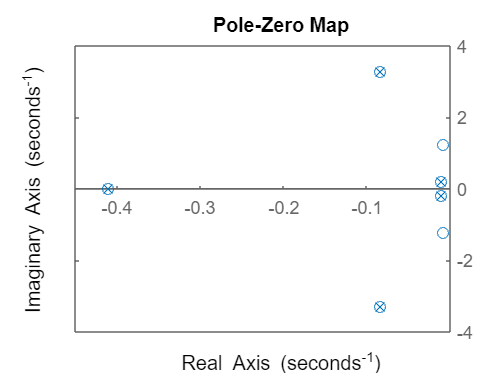

% Pole zero plot

pzplot(G_mix);
ax = gca;           % Get current axes
ax.XAxisLocation = 'origin';  % Move horizontal axis to origin
ax.YAxisLocation = 'origin';  % Move vertical axis to origin
axis([-0.45 0 -4 4]);

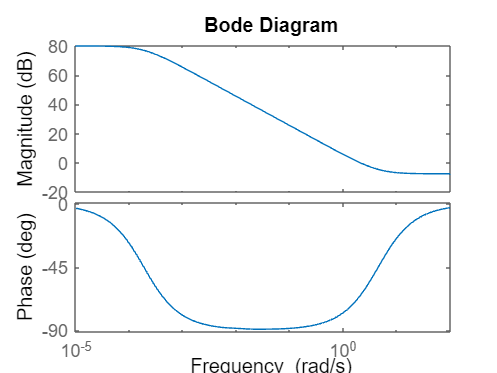

%  Design an appropriate Wp11
%
% Specifications:
% - Cutoff frequency: f_c = 0.3 Hz
% - Low-frequency disturbance attenuation: |S(jw)| <= 10^-4 for low w
% - Maximum sensitivity: ||S||_inf = 2.4
%
% Weight structure
% w_pi(s) = (s/M_i + omega_Bi) / (s + omega_Bi*A_i),  A_i << 1

f_cutoff = 0.3;
w_c = 2*pi*f_cutoff;
attenuation = 10^-4;
H_inf_norm = 2.4;

Wp11 = tf([1/H_inf_norm, w_c], [1, w_c*attenuation]); %Slide 28 Lecture 3
Wp = [Wp11, 0; 0, 0.1];
Wu = [0.01, 0; 0, tf([5*10^-3, 7*10^-4, 5*10^-5], [1, 14*10^-4, 10^-6])];

bode(Wp11)

% Generalized plant

P = minreal(augw(G_mix, Wp, Wu, []));

10 states removed.



disp('Generalized Plant P constructed.');

Generalized Plant P constructed.


disp('Inputs: Disturbance w, Control u');

Inputs: Disturbance w, Control u



% Check the size of P
size(P)

State-space model with 6 outputs, 4 inputs, and 8 states.


% H-infinity Controller Synthesis

[n_out, n_in] = size(G_mix);

[K, CL, gamma] = hinfsyn(P, n_out, n_in); 

fprintf('H-infinity Synthesis Complete.\n');

H-infinity Synthesis Complete.


fprintf('Achieved Gamma: %.4f\n', gamma);

Achieved Gamma: 0.6215



%% Stability and State Analysis
fprintf('\n=== Analysis Results ===\n');


=== Analysis Results ===



% 1. Number of States
states_K = order(K);
states_P = order(P);
fprintf('Number of states in Controller K: %d\n', states_K);

Number of states in Controller K: 8


fprintf('Number of states in Generalized Plant P: %d\n', states_P);

Number of states in Generalized Plant P: 8


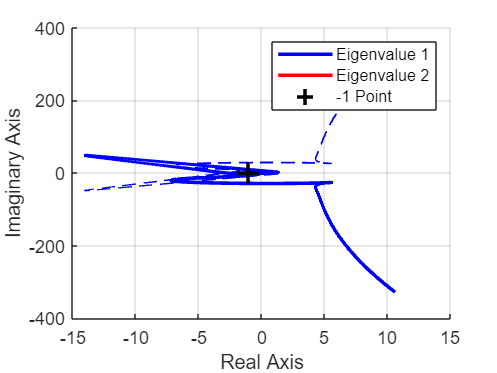


L = G_mix*K;

% Generalized Nyquist Plot (Characteristic Loci)
% Reference: Adapted from Mohamed Belkhayat's method
figure;

% Frequency vector
w = logspace(-2, 2, 1000);

% Calculate frequency response of the loop transfer function L
L_resp = freqresp(L, w);
[n_out_L, n_in_L, n_w] = size(L_resp);

% Initialize eigenvalue storage
E = zeros(n_out_L, n_w);

% Loop through each frequency point to calculate eigenvalues
for k = 1:n_w
    % Extract the L matrix at frequency k
    L_k = L_resp(:, :, k);
    
    % Calculate eigenvalues
    E(:, k) = eig(L_k);
end

% Plot the Characteristic Loci
figure;
hold on;
colors = ['b', 'r', 'g', 'm'];

for i = 1:n_out_L
    % Plot positive frequencies (Real vs Imag)
    plot(real(E(i, :)), imag(E(i, :)), colors(i), 'LineWidth', 2, 'DisplayName', sprintf('Eigenvalue %d', i));
    
    % Plot negative frequencies (Real vs -Imag) - Conjugate
    plot(real(E(i, :)), -imag(E(i, :)), [colors(i) '--'], 'LineWidth', 1, 'HandleVisibility', 'off');
end

% Mark the -1
plot(-1, 0, 'k+', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', '-1 Point');

grid on;
xlabel('Real Axis'); ylabel('Imaginary Axis');
legend('show');
hold off;

disp(['Zoom in on interactive plot to see the evolution of the loci aroudn the critical point'])

Zoom in on interactive plot to see the evolution of the loci aroudn the critical point


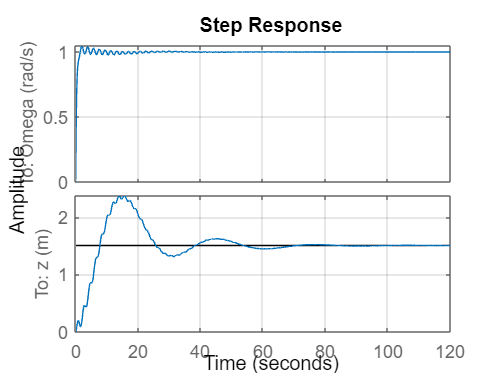

% Plot Step Response (For step inputs on the control channels)
T = feedback(G_mix*K,eye(n_out));
u = ones(2,1);
step(T*u);
grid on;    


% Loop Transfer Function L = G*K
L = G_mix * K;

% Closed-loop Transfer Function T = (I + GK)^-1 GK
T = feedback(L, eye(n_out));

% Get Step Info
h = stepinfo(T);

% Channel 1: Beta (Input 1) -> Omega (Output 1)
fprintf('\n--- Beta to Omega (T_11) ---\n');


--- Beta to Omega (T_11) ---


fprintf('Rise Time:          %.4f s\n', h(1,1).RiseTime);

Rise Time:          0.6718 s


fprintf('Settling Time:      %.4f s\n', h(1,1).SettlingTime);

Settling Time:      14.1694 s


fprintf('Overshoot:          %.4f %%\n', h(1,1).Overshoot);

Overshoot:          4.6426 %


fprintf('Steady-State Value: %.4f\n', dcgain(T(1,1)));

Steady-State Value: 0.9999



% Channel 2: Beta (Input 1) -> Z (Output 2)
fprintf('\n--- Beta to Z (T_21) ---\n');


--- Beta to Z (T_21) ---


fprintf('Rise Time:          %.4f s\n', h(2,1).RiseTime);

Rise Time:          6.8039 s


fprintf('Settling Time:      %.4f s\n', h(2,1).SettlingTime);

Settling Time:      66.5787 s


fprintf('Overshoot:          %.4f %%\n', h(2,1).Overshoot);

Overshoot:          58.1573 %


fprintf('Steady-State Value: %.4f\n', dcgain(T(2,1)));

Steady-State Value: 1.5035



%% 5. Bandwidth Analysis (Sensitivity)
fprintf('\n=== Bandwidth Analysis ===\n');


=== Bandwidth Analysis ===


% Sensitivity Function S = (I + L)^-1
S = feedback(eye(n_out), L);

freqs = logspace(-4, 4, 5000);
[mag_S, ~, w_out] = bode(S, freqs);

% Bandwidth (Sensitivity S_11 crossing -3dB from below)
mag_S11 = squeeze(mag_S(1, 1, :));
idx_bw1 = find(20*log10(mag_S11) >= -3, 1, 'first');
if ~isempty(idx_bw1)
    fprintf('Bandwidth (S_11):   %.4f rad/s\n', w_out(idx_bw1));
else
    fprintf('Bandwidth (S_11):   Not found\n');
end

Bandwidth (S_11):   2.7396 rad/s



% Bandwidth (Sensitivity S_22 crossing -3dB from below)
mag_S22 = squeeze(mag_S(2, 2, :));
idx_bw2 = find(20*log10(mag_S22) >= -3, 1, 'first');
if ~isempty(idx_bw2)
    fprintf('Bandwidth (S_22):   %.4f rad/s\n', w_out(idx_bw2));
else
    fprintf('Bandwidth (S_22):   Not found\n');
end

Bandwidth (S_22):   0.0001 rad/s



% Step wind (disturbance)
figure;
stepWind(FWT,K)


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 0.3602     | 65.7279    | NaN        | 8829.0490  | 0.0489     | 0.7482     | 0.0000    
z (m)                     | 17.6694    | 470.9028   | 169.8856   | 51.3676    | 0.6172     | 32.2543    | -0.2287   
Beta (deg)                | 1.4508     | 122.6306   | 38.5728    | -0.0000    | 3.8233     | 24.3570    | 2.7591    
tau_e (Nm)                

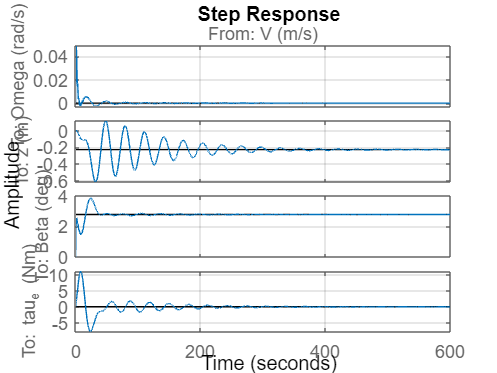

grid on;

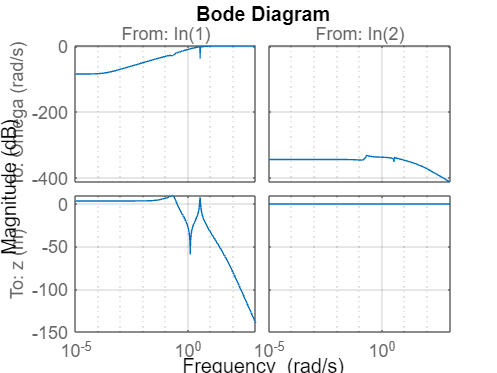


% Sensitivity plot
S = eye(n_out) - T;
bodemag(S)
grid on;

### Fixed Structure Control Design

% SISO transfer functions
beta_to_omega_r = FWT(1, 1);
beta_to_z = FWT(2, 1);
tau_to_omega_r = FWT(1, 2);
tau_to_z = FWT(2, 2);

% MIMO plant constructed as block matrix of SISO transfer functions
G = [tf(beta_to_omega_r), tf(tau_to_omega_r);
     tf(beta_to_z),     tf(tau_to_z)];

% Performance specifications for Wp11
f_cutoff = 0.3; % Hz
w_c = 2*pi*f_cutoff; % rad/s
attenuation = 10^-4;
H_inf_norm = 2.4;

% Construct performance weights
Wp11 = tf([1/H_inf_norm, w_c], [1, w_c*attenuation]); %Slide 28 Lecture 3
Wp = [Wp11, 0; 
    0, 0.1];
Wu = [0.01, 0; 
    0, tf([5*10^-3, 7*10^-4, 5*10^-5], [1, 14*10^-4, 10^-6])];

% The second input (torque) is used minimally

s = tf('s');

Kp1 = realp ('Kp1' ,1) ;
Ki1 = realp ('Ki1' ,1) ;
Kd1 = realp ('Kd1' ,1) ;
Tf1 = realp ('Tf1' ,1) ;

Kp2 = realp ('Kp2' ,1) ;
Ki2 = realp ('Ki2' ,1) ;
Kd2 = realp ('Kd2' ,1) ;
Tf2 = realp ('Tf2' ,1) ;

C11 = Kp1 + Ki1/s + (Kd1*s)/(Tf1*s + 1);
C21 = Kp2 + (Kd2*s)/(Tf2*s + 1); %No K_i term included to ensure tau- > 0 

%class(C_struct_mimo)

Wp1_struc = Wp(1, 1) ;
Wp1_struc . u = 'e1';
Wp1_struc . y = 'z11';

Wp2_struc = Wp(2, 2) ;
Wp2_struc . u = 'e2';
Wp2_struc . y = 'z12';
% ------------------------------------------------------------
Wu1_struc = Wu(1, 1) ;
Wu1_struc . u = 'u1';
Wu1_struc . y = 'z21';

Wu2_struc = Wu(2, 2) ;
Wu2_struc . u = 'u2';
Wu2_struc . y = 'z22';
% --------------------------------------------------------------
G_mimo11 = -1* G(1, 1) ;
G_mimo11 . u = 'u1';
G_mimo11 . y = 'y11';

G_mimo12 = -1* G(1, 2) ; %original (2,1)
G_mimo12 . u = 'u2';
G_mimo12 . y = 'y12';    %original y21

G_mimo21 = -1* G(2,1) ; %original (1,2)
G_mimo21 . u = 'u1';
G_mimo21 . y = 'y21';   %original y12

G_mimo22 = -1* G(2, 2) ;
G_mimo22 . u = 'u2';
G_mimo22 . y = 'y22';

SumG_1 = sumblk('y1 = y11 + y12')

SumG_1 =
 
  From input "y11" to output "y1":
  1
 
  From input "y12" to output "y1":
  1
 
Static gain.
Model Properties


SumG_2 = sumblk('y2 = y21 + y22')

SumG_2 =
 
  From input "y21" to output "y2":
  1
 
  From input "y22" to output "y2":
  1
 
Static gain.
Model Properties


% ------------------------------------------------------------
C_mimo1 = C11 ;
C_mimo1 . u = 'v1';
C_mimo1 . y = 'u1';

C_mimo2 = C21 ;
C_mimo2 . u = 'v1';
C_mimo2 . y = 'u2';
%
Sum1 = sumblk('e1 = r + y1'); 
Sum2 = sumblk('e2 = r + y2');
Sum3 = sumblk('v1 = -e1');
% Mimo_Con = connect ( G_mimo , Wp_struc, Wu_struc , C_mimo , Sum1, Sum2 , {'r'} , {'y','z1', 'z2'}) ;
Mimo_Con = connect ( Wp1_struc,Wp2_struc,Wu1_struc, Wu2_struc,G_mimo11, G_mimo12, G_mimo21, G_mimo22, C_mimo1, C_mimo2, SumG_1, SumG_2, Sum1, Sum2, Sum3  , {'r'} , {'z11', 'z12', 'z21', 'z22'}) 

Generalized continuous-time state-space model with 4 outputs, 1 inputs, 34 states, and the following blocks:
  Kd1: Scalar parameter, 1 occurrences.
  Kd2: Scalar parameter, 1 occurrences.
  Ki1: Scalar parameter, 1 occurrences.
  Kp1: Scalar parameter, 1 occurrences.
  Kp2: Scalar parameter, 1 occurrences.
  Tf1: Scalar parameter, 1 occurrences.
  Tf2: Scalar parameter, 1 occurrences.



opt = hinfstructOptions ('Display','final','RandomStart', 20) ;
[N_mimo, gamma_struct, info_struct] = hinfstruct (Mimo_Con, opt) ;

Final: Peak gain = 2.04, Iterations = 82
Final: Peak gain = 2.03, Iterations = 115
Final: Peak gain = 2.03, Iterations = 94
Final: Peak gain = 2.03, Iterations = 106
Final: Peak gain = 2.03, Iterations = 109
Final: Peak gain = 2.03, Iterations = 94
Final: Peak gain = 2.03, Iterations = 103
Final: Peak gain = 2.03, Iterations = 92
Final: Peak gain = 2.03, Iterations = 85
Final: Peak gain = 2.03, Iterations = 100
Final: Peak gain = 2.03, Iterations = 90
Final: Peak gain = 2.03, Iterations = 93
Final: Peak gain = 2.03, Iterations = 84
Final: Peak gain = 2.03, Iterations = 92
Final: Peak gain = 2.03, Iterations = 83
Final: Peak gain = 2.03, Iterations = 85
Final: Peak gain = 2.03, Iterations = 94
Final: Peak gain = 2.03, Iterations = 100
Final: Peak gain = 2.03, Iterations = 79
Final: Peak gain = 2.03, Iterations = 96
Final: Peak gain = 2.03, Iterations = 82



% Extract controller gains :
Kp_opt1 = N_mimo . Blocks . Kp1 . Value 

Kp_opt1 = -21.8657

Ki_opt1 = N_mimo . Blocks . Ki1 . Value 

Ki_opt1 = 7.2731

Kd_opt1 = N_mimo . Blocks . Kd1 . Value 

Kd_opt1 = 213.5230

Tf_opt1 = N_mimo . Blocks . Tf1 . Value 

Tf_opt1 = 2.4777


Kp_opt2 = N_mimo . Blocks . Kp2 . Value 

Kp_opt2 = 5.3584

%Ki_opt2 = N_mimo . Blocks . Ki2 . Value 
Kd_opt2 = N_mimo . Blocks . Kd2 . Value 

Kd_opt2 = 4.2403e+04

Tf_opt2 = N_mimo . Blocks . Tf2 . Value 

Tf_opt2 = 114.5181

Kp_opt1 = -4.1516e+03

Kp_opt1 = -4.1516e+03

Ki_opt1 = 165.5579

Ki_opt1 = 165.5579

Kd_opt1 = 1.0831e+05

Kd_opt1 = 108310

Tf_opt1 = 25.2822

Tf_opt1 = 25.2822

Kp_opt2 = 1.2254e+03

Kp_opt2 = 1.2254e+03

Kd_opt2 = -3.3201e+03

Kd_opt2 = -3.3201e+03

Tf_opt2 = 2.7810

Tf_opt2 = 2.7810

s = tf('s');

Kfb_opt_mimo = [Kp_opt1 + Ki_opt1 / s + ( Kd_opt1 * s ) /( Tf_opt1 * s +1), 0;
                Kp_opt2 + ( Kd_opt2 * s ) /( Tf_opt2 * s +1), 0]

Kfb_opt_mimo =
 
  From input 1 to output...
       3348 s^2 + 34.07 s + 165.6
   1:  --------------------------
             25.28 s^2 + s
 
       87.74 s + 1225
   2:  --------------
        2.781 s + 1
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties



ss(Kfb_opt_mimo)

ans =
 
  A = 
             x1        x2        x3
   x1  -0.03955         0         0
   x2    0.0625         0         0
   x3         0         0   -0.3596
 
  B = 
       u1  u2
   x1   8   0
   x2   0   0
   x3  16   0
 
  C = 
            x1       x2       x3
   y1  -0.4864     13.1        0
   y2        0        0    26.83
 
  D = 
          u1     u2
   y1  132.4      0
   y2  31.55      0
 
Continuous-time state-space model.


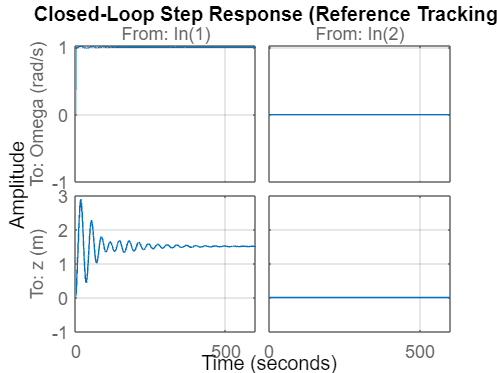

L = -G*Kfb_opt_mimo;
S = feedback(eye(2), L);
T = feedback(L, eye(2));

figure;
step(T);
grid on;
title('Closed-Loop Step Response (Reference Tracking)');


S1 = stepinfo(T(1, 1));

disp(['Rise Time Omega: ', num2str(S1.RiseTime), ' s']);

Rise Time Omega: 0.21445 s


disp(['Settling Time Omega: ', num2str(S1.SettlingTime), ' s']);

Settling Time Omega: 18.5036 s


disp(['Overshoot Omega: ', num2str(S1.Overshoot), ' %']);

Overshoot Omega: 2.128 %


disp(['Steady-State Value Omega: ', num2str(S1.SettlingMin)]);

Steady-State Value Omega: 0.90043



S2 = stepinfo(T(2, 1));

disp(['Rise Time z: ', num2str(S2.RiseTime), ' s']);

Rise Time z: 7.3159 s


disp(['Settling Time z: ', num2str(S2.SettlingTime), ' s']);

Settling Time z: 369.7721 s


disp(['Overshoot z: ', num2str(S2.Overshoot), ' %']);

Overshoot z: 92.4489 %


disp(['Steady-State Value z: ', num2str(S2.SettlingMin)]);

Steady-State Value z: 0.43297


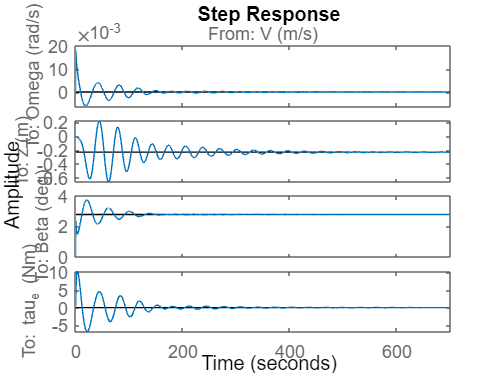


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 0.1348     | 243.0256   | NaN        | 53057.8803 | 0.0180     | 0.4044     | 0.0000    
z (m)                     | 10.3672    | 605.5907   | 189.8435   | 98.5889    | 0.6603     | 61.7336    | -0.2278   
Beta (deg)                | 10.0749    | 142.0559   | 34.9522    | -0.0000    | 3.7226     | 21.5663    | 2.7585    
tau_e (Nm)                


stepWind(FWT, Kfb_opt_mimo)


[P_sim, t, y] = stepWind_out(FWT, -Kfb_opt_mimo);

for i = 1:2
    yi = y(:,i);       % output i
    y0 = yi(end);      % steady-state value
    e = yi - y0;       % deviation

    % Peak deviation
    peak_dev = max(abs(e));

    % Recovery time (2% band)
    eps = 0.02 * peak_dev;   
    idx = find(abs(e) > eps, 1, 'last');
    recovery_time = t(idx);

    %bw = bandwidth(P_sim(i, 1));

    % Display
    disp(['Output ', num2str(i)]);
    disp(['Peak deviation: ', num2str(peak_dev)]);
    disp(['Recovery time: ', num2str(recovery_time), ' s']);
    %disp(['Bandwidth: ', num2str(bw), ' rad/s']);
    disp('------------------------------------');
end

Output 1


Peak deviation: 2.200166739523789e+23


Recovery time: 5.389 s


------------------------------------


Output 2


Peak deviation: 1.163167848797486e+22


Recovery time: 5.389 s


------------------------------------


% augw(G, W1, W2, W3)
P = minreal(augw(G, Wp, Wu));

10 states removed.



disp('Generalized Plant P constructed.');

Generalized Plant P constructed.


disp('Inputs: Disturbance w, Control u');

Inputs: Disturbance w, Control u



% Check the size of P
size(P)

State-space model with 6 outputs, 4 inputs, and 8 states.



% H-infinity Synthesis
[n_out, n_in] = size(G);

%% 6. H-infinity Controller Synthesis
disp('Synthesizing H-infinity controller...');

Synthesizing H-infinity controller...


[K, CL, gamma] = hinfsyn(P, n_out, n_in);

fprintf('H-infinity Synthesis Complete.\n');

H-infinity Synthesis Complete.


fprintf('Achieved Gamma: %.4f\n', gamma);

Achieved Gamma: 0.6215


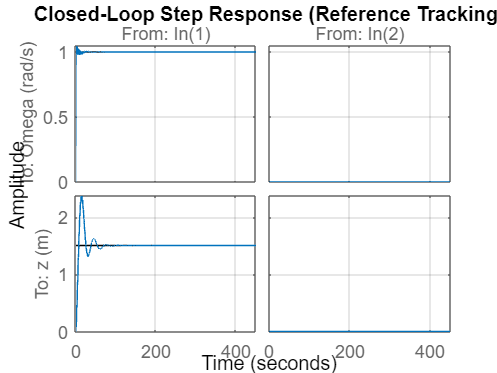


% Compute Sensitivity S and Complementary Sensitivity T
L1 = G*K;
S1 = feedback(eye(n_out), L1);
T1 = feedback(L1, eye(n_out));

% % Plot Sensitivity vs Inverse Performance Weight
% figure;
% sigma(S, 'b', inv(W_p), 'r--');
% grid on;
% legend('Sensitivity \sigma(S)', 'Inverse Weight \sigma(W_p^{-1})');
% title('Sensitivity Function vs Performance Bound');
% xlabel('Frequency (rad/s)');
% ylabel('Magnitude (dB)');

% Plot Step Response
figure;
step(T1);
grid on;
title('Closed-Loop Step Response (Reference Tracking)');


figure;
stepWind(FWT, -K);


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 0.3602     | 65.7279    | NaN        | 8829.0489  | 0.0489     | 0.7482     | 0.0000    
z (m)                     | 17.6694    | 470.9028   | 169.8856   | 51.3676    | 0.6172     | 32.2543    | -0.2287   
Beta (deg)                | 1.4508     | 122.6306   | 38.5728    | -0.0000    | 3.8233     | 24.3570    | 2.7591    
tau_e (Nm)                

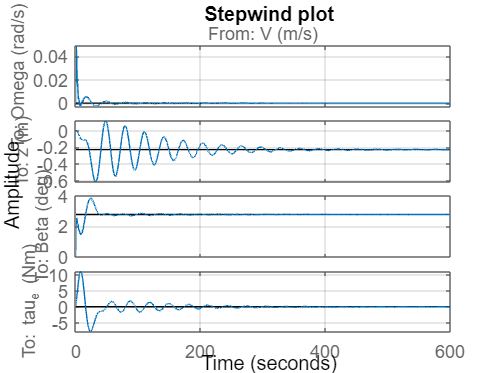

grid on;
title('Stepwind plot');


% Display Controller
disp('Designed Controller K:');

Designed Controller K:


K

K =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1   -72.51   -70.75    99.77   -204.4   -9.879   -9.818    7.541    2.365
   x2    26.83    25.91   -37.58    75.63    5.106    1.085   -2.431   -1.305
   x3    198.9    195.3   -272.6    558.4    25.61    26.13   -18.98   -6.737
   x4    113.6    111.5   -155.6    319.2     14.4    15.72   -10.99   -3.743
   x5   -323.1   -318.5    443.8   -908.9   -41.27   -42.13    32.17    10.56
   x6    0.667    2.379   0.3321    1.022   -1.395  0.01441    1.613  -0.2569
   x7    142.6    140.3   -194.9    399.4    19.38    17.56   -11.05   -5.737
   x8   -76.36   -77.15    107.4   -219.6   -5.724   -12.75    15.89  -0.4753
 
  B = 
               u1          u2
   x1      0.2876   4.566e-17
   x2      0.2555   1.484e-17
   x3      -0.387   6.636e-17
   x4      0.8366  -2.448e-18
   x5   -0.006755    6.96e-17
   x6     0.01782  -4.663e-17
   x7    -0.04417   5.501e-17
   x8   5.348e-05  -2.341e-17
 
  C 

L = -G*Kfb_opt_mimo;
S = feedback(eye(2), L);
T = feedback(L, eye(2));

w = logspace(-4, 2, 2000); 

T1 = feedback(G*K, eye(2));
S_test = feedback(eye(2), G*K);

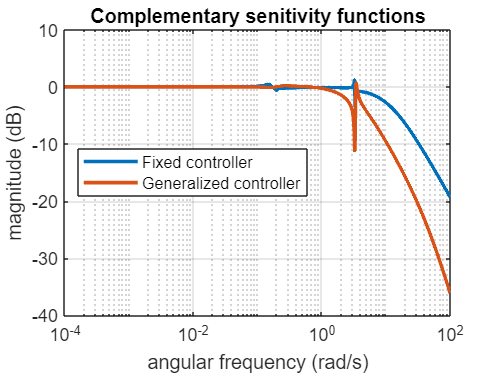

[mag1, phase1, w1] = bode(T(1,1),w);
[mag2, phase2, w2] = bode(T1(1,1),w);

figure;
semilogx(w, squeeze(20*log10(mag1)), 'LineWidth', 2);
hold on;
semilogx(w, squeeze(20*log10(mag2)), 'LineWidth', 2);
hold off;
grid on;
l = legend('Fixed controller', 'Generalized controller');
l.Location = 'west';
title('Complementary senitivity functions');
xlabel('angular frequency (rad/s)')
ylabel('magnitude (dB)')

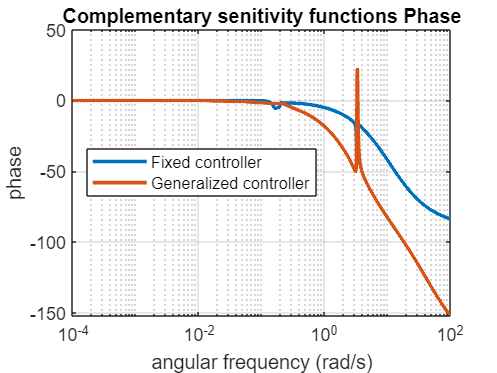


figure;
semilogx(w, squeeze(phase1), 'LineWidth', 2);
hold on;
semilogx(w, squeeze(phase2), 'LineWidth', 2);
hold off;
grid on;
l = legend('Fixed controller', 'Generalized controller');
l.Location = 'west';
title('Complementary senitivity functions Phase');
xlabel('angular frequency (rad/s)')
ylabel('phase')

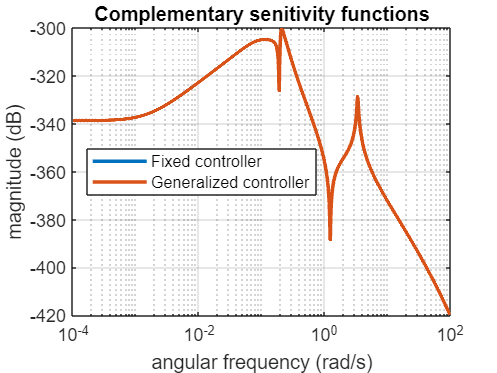

[mag1, phase1, w1] = bode(T(2,2),w);
[mag2, phase2, w2] = bode(T1(2,2),w);
mag1_ = 20*log10(mag1);
mag2_ = 20*log10(mag2);
figure;
semilogx(w, squeeze(mag1_), 'LineWidth', 2);
hold on;
semilogx(w, squeeze(mag2_), 'LineWidth', 2);
hold off;
grid on;
l = legend('Fixed controller', 'Generalized controller');
l.Location = 'west';
title('Complementary senitivity functions');
xlabel('angular frequency (rad/s)')
ylabel('magnitude (dB)')

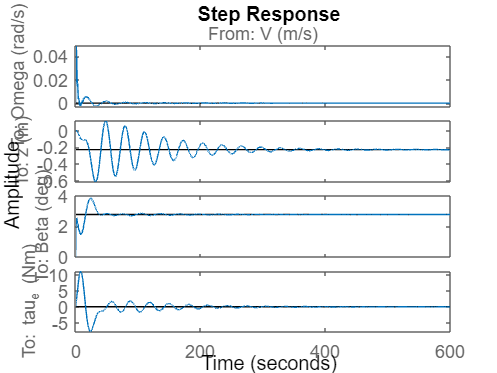


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 0.3602     | 65.7279    | NaN        | 8829.0489  | 0.0489     | 0.7482     | 0.0000    
z (m)                     | 17.6694    | 470.9028   | 169.8856   | 51.3676    | 0.6172     | 32.2543    | -0.2287   
Beta (deg)                | 1.4508     | 122.6306   | 38.5728    | -0.0000    | 3.8233     | 24.3570    | 2.7591    
tau_e (Nm)                

stepWind(FWT, -K);

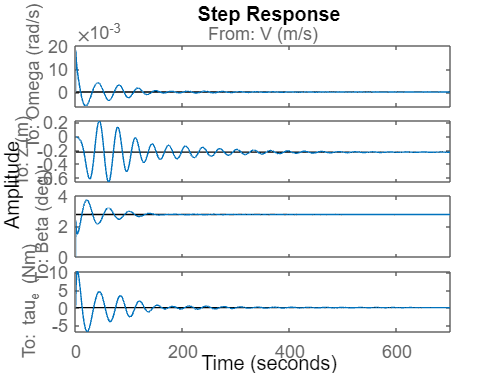


                                        Step Response Performance Metrics (2% Settling)                                        
Output Channel            | RiseTime   | Recov/Set  | Overshoot% | Undershoot% | Peak/Dev   | PeakTime   | FinalValue
--------------------------|------------|------------|------------|------------|------------|------------|------------
Omega (rad/s)             | 0.1348     | 243.0256   | NaN        | 53057.8803 | 0.0180     | 0.4044     | 0.0000    
z (m)                     | 10.3672    | 605.5907   | 189.8435   | 98.5889    | 0.6603     | 61.7336    | -0.2278   
Beta (deg)                | 10.0749    | 142.0559   | 34.9522    | -0.0000    | 3.7226     | 21.5663    | 2.7585    
tau_e (Nm)                

stepWind(FWT, Kfb_opt_mimo);

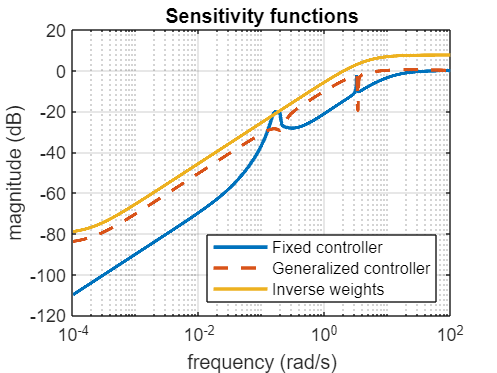

figure;
[mag1, phase1, w1] = bode(S(1,1), w); 
[mag2, phase2, w2] = bode(S_test(1,1), w); 
[mag3, phase3, w3] = bode(1/Wp11, w);
mag1 = squeeze(20*log10(mag1));
mag2 = squeeze(20*log10(mag2));
mag3 = squeeze(20*log10(mag3));
figure;
semilogx(w, mag1, 'LineWidth', 2);
hold on;
semilogx(w2, mag2, '--', 'LineWidth', 2);
hold on;
semilogx(w, mag3, 'LineWidth', 2);
hold off;
grid on;
l = legend('Fixed controller', 'Generalized controller', 'Inverse weights');
l.Location = 'southeast';
xlabel('angular frequency (rad/s)')
ylabel('magnitude (dB)')
title('Sensitivity functions')
title('Sensitivity functions')
xlabel('frequency (rad/s)')


idx_cross1 = find(mag1 >= -3, 1, 'first')

idx_cross1 = 1505

omega1 = w(idx_cross1)

omega1 = 3.2678


idx_cross2 = find(mag2 >= -3, 1, 'first')

idx_cross2 = 1480

omega2 = w(idx_cross2)

omega2 = 2.7493

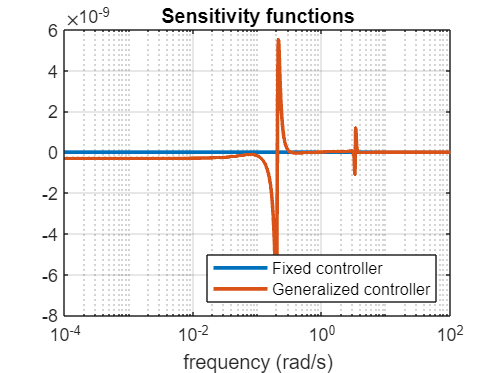

figure;
[mag1, phase1, w1] =bode(S(2,2),w); 
[mag2, phase2, w2] =bode(S_test(2,2),w); 
mag12 = squeeze(20*log10(mag1));
mag22 = squeeze(20*log10(mag2));

figure;
semilogx(w1, mag12, 'LineWidth', 2);
hold on;
semilogx(w2, mag22, 'LineWidth', 2);
hold off;

grid on;
l = legend('Fixed controller', 'Generalized controller');
l.Location = 'southeast';

title('Sensitivity functions')
xlabel('frequency (rad/s)')

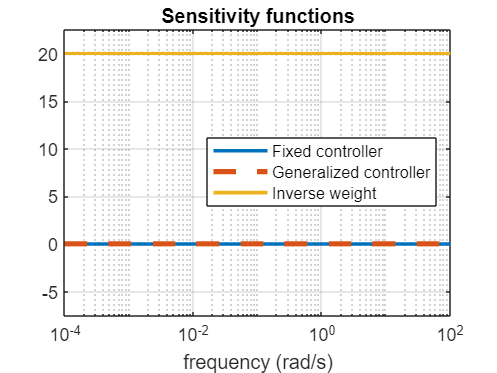

figure;
[mag1,phase1,wout1] = bode(S(2,2),w);       % convert to arrays
mag1 = squeeze(mag1);  % remove singleton dims
semilogx(wout1, 20*log10(mag1), 'LineWidth', 2); hold on;

[mag2,phase2,wout2] = bode(S_test(2,2),w);
mag2 = squeeze(mag2);
semilogx(wout2, 20*log10(mag2),'--', 'LineWidth',3 );

[mag3,phase3,wout3] = bode(1/Wp(2,2),w);
mag3 = squeeze(mag3);
semilogx(wout3, 20*log10(mag3), 'LineWidth', 2);
grid on;
l = legend('Fixed controller','Generalized controller','Inverse weight');
l.Location = 'east';

yl = ylim;                % get current limits
padding = 0.1*(yl(2)-yl(1));  % 10% padding

ylim([yl(1) - padding, yl(2) + padding]);

title('Sensitivity functions');
title('Sensitivity functions')
xlabel('frequency (rad/s)')
hold off;

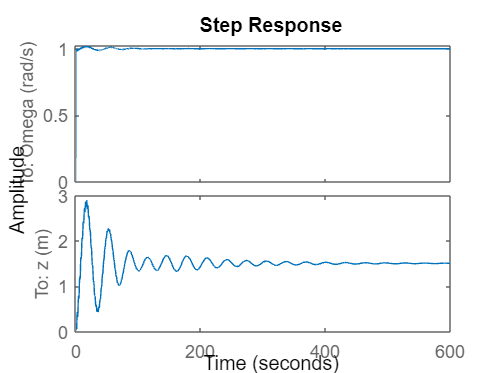

step(T(:,1));

stepinfo(T(1,1))

ans = struct with fields:
         RiseTime: 0.2145
    TransientTime: 18.5036
     SettlingTime: 18.5036
      SettlingMin: 0.9004
      SettlingMax: 1.0213
        Overshoot: 2.1280
       Undershoot: 0
             Peak: 1.0213
         PeakTime: 16.4525

stepinfo(T(2,1))

ans = struct with fields:
         RiseTime: 7.3159
    TransientTime: 369.7721
     SettlingTime: 369.7721
      SettlingMin: 0.4330
      SettlingMax: 2.8937
        Overshoot: 92.4489
       Undershoot: 0
             Peak: 2.8937
         PeakTime: 17.8876

### Function List

function [P_sim, t, y] = stepWind_out(FWT,K)
% STEPWIND Applies a wind step disturbance to the closed loop consisting of
% the FWT and a controller K of choice (may be SISO or MIMO).

if size(K,1) == 1 % adapt if SISO
    K = blkdiag(K,0);
end
G = FWT(:,1:2);

% Contstruct CL for simulation
G_sim = G;
G_sim.u = 'u';
G_sim.y = 'y_plant';

K_sim = K;
K_sim.u = 'y_meas';
K_sim.y = 'u';

Gd_sim = FWT(:,3);
Gd_sim.u = 'V';
Gd_sim.y = 'y_dist';

Sum_sim = sumblk('y_meas = y_plant + y_dist', 2);

P_sim = connect(G_sim,K_sim,Gd_sim,Sum_sim,{'V'},{'y_meas','u'});

P_sim.InputName = {'V (m/s)'};
P_sim.OutputName = [G.OutputName; G.InputName];

[y,t] = step(P_sim);

end

function [] = stepWind(FWT,K)
% STEPWIND Applies a wind step disturbance to the closed loop consisting of
% the FWT and a controller K of choice (may be SISO or MIMO).

if size(K,1) == 1 % adapt if SISO
    K = blkdiag(K,0);
end
G = FWT(:,1:2);

% Contstruct CL for simulation
G_sim = G;
G_sim.u = 'u';
G_sim.y = 'y_plant';

K_sim = K;
K_sim.u = 'y_meas';
K_sim.y = 'u';

Gd_sim = FWT(:,3);
Gd_sim.u = 'V';
Gd_sim.y = 'y_dist';

Sum_sim = sumblk('y_meas = y_plant + y_dist', 2);

P_sim = connect(G_sim,K_sim,Gd_sim,Sum_sim,{'V'},{'y_meas','u'});

P_sim.InputName = {'V (m/s)'};
P_sim.OutputName = [G.OutputName; G.InputName];


step(P_sim)

% Get response data to handle small final values (disturbance rejection)
[y, t] = step(P_sim);
[~, n_out] = size(y);

% Loop through outputs to calculate stepinfo
for i = 1:n_out
    y_i = y(:, i);
    peak_val = max(abs(y_i));
    final_val = y_i(end);
    
    % Check for Disturbance Rejection (Impulse-like) vs Step Tracking
    % If final value is small (< 5% of peak), treat as settling to zero (Disturbance).
    is_disturbance = (peak_val > 0) && (abs(final_val) < 0.05 * peak_val);
    
    if is_disturbance
        % Disturbance Rejection: Use user-defined Recovery Time and Peak Deviation
        y0 = final_val;
        e = y_i - y0;
        
        % Peak deviation
        peak_dev = max(abs(e));
        
        % Recovery time (2% band of peak deviation)
        eps_bound = 0.02 * peak_dev;
        idx = find(abs(e) > eps_bound, 1, 'last');
        if isempty(idx)
            recovery_time = 0;
        else
            recovery_time = t(idx);
        end
        
        % Get a template structure from stepinfo to ensure compatibility
        si = stepinfo(y_i, t, final_val, 'SettlingTimeThreshold', 0.02);
        
        % Overwrite with custom metrics
        si.SettlingTime = recovery_time;
        si.Peak = peak_dev;
        si.Overshoot = NaN; 
        
        % Calculate Rise Time manually (10% to 90% of Peak Deviation)
        [~, idx_peak] = max(abs(e));
        abs_e = abs(e);
        idx_10 = find(abs_e(1:idx_peak) >= 0.1 * peak_dev, 1, 'first');
        idx_90 = find(abs_e(1:idx_peak) >= 0.9 * peak_dev, 1, 'first');
        
        if ~isempty(idx_10) && ~isempty(idx_90)
            si.RiseTime = t(idx_90) - t(idx_10);
        else
            si.RiseTime = NaN;
        end
    else
        % Standard Step Tracking
        si = stepinfo(y_i, t, final_val, 'SettlingTimeThreshold', 0.02);
    end
    
    % Store Final Value
    si.FinalValue = final_val;

    if i == 1
        S = si;
        S(n_out) = si; % Preallocate structure array
    else
        S(i) = si;
    end
end

% Format and display table
fprintf('\n================================================================================================================================\n');
fprintf('                                        Step Response Performance Metrics (2%% Settling)                                        \n');
fprintf('================================================================================================================================\n');
fprintf('%-25s | %-10s | %-10s | %-10s | %-10s | %-10s | %-10s | %-10s\n', ...
    'Output Channel', 'RiseTime', 'Recov/Set', 'Overshoot%', 'Undershoot%', 'Peak/Dev', 'PeakTime', 'FinalValue');
fprintf('--------------------------|------------|------------|------------|------------|------------|------------|------------\n');

output_names = P_sim.OutputName;
% Handle case where OutputName might be empty or not set correctly
if isempty(output_names) || length(output_names) ~= length(S)
    output_names = cell(length(S), 1);
    for i=1:length(S), output_names{i} = sprintf('Output %d', i); end
end

for i = 1:length(S)
    fprintf('%-25s | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f\n', ...
        output_names{i}, S(i).RiseTime, S(i).SettlingTime, S(i).Overshoot, S(i).Undershoot, S(i).Peak, S(i).PeakTime, S(i).FinalValue);
end
fprintf('================================================================================================================================\n');

end